f = @(x) -12-21.*x+18.*x.^2-2.75.*x.^3;
fs = sym(f)

$$fs = -\frac{11\,x^{3}}{4}+18\,x^{2}-21\,x-12$$

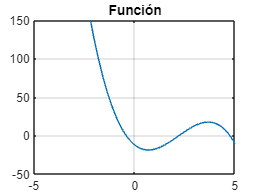

fplot(f)
title("Función")
xlim([-5, 5])
ylim([-50, 150])
grid on


a = -5;
b = 5;
[x0, it] = biseccion(f, a, b)

x0 = -0.4147

it = 52

function [x, i] = biseccion(f, a, b)
    if sign(f(a)) * sign(f(b)) >= 0
        error("El intervalo no contiene a la raíz")
    end

    MAX = 52;
    x = a;
    i = 0;
    while f(x) ~=0 && abs((b - a) / b) > eps && i < MAX
        if sign(f(a)) == sign(f(x))
            a = x;
        else
            b = x;
        end
        x = (a + b) / 2;
        i = i + 1;
    end
end